# 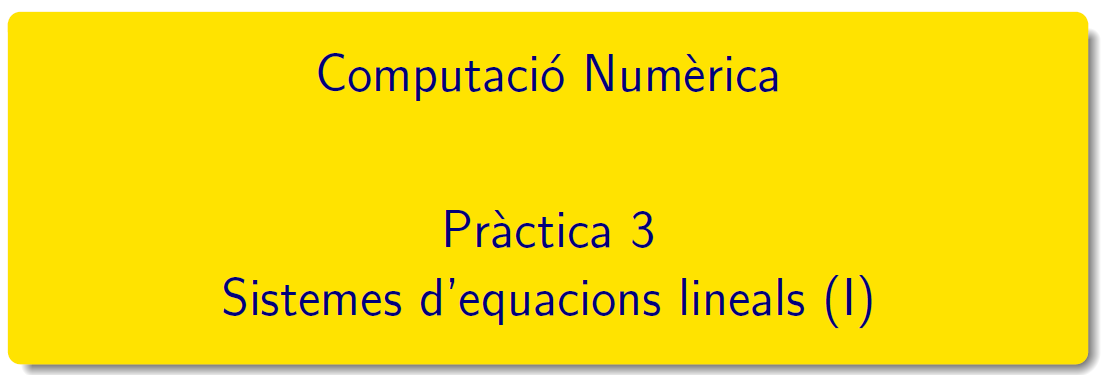

=======================================================================================

# Pràctica 3 - Primera part

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document  CN-tema2-QT2223.pdf que podeu trobar en el campus virtual. 

[Matrius de Matlab](https://es.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html) (resum de com treballar amb matrius) Biblioteca de [matrius en Matlab](https://es.mathworks.com/help/matlab/constants-and-test-matrices.html?lang=en), i més matrius en Matlab [gallery](https://es.mathworks.com/help/matlab/ref/gallery.html)

#### **Exercici 1**. Àlgebra lineal

Calculeu  el determinant, la transposta, la inversa, els valors propis i els vectors propis de la matriu A definida per


$$A=\left(\begin{array}{rrr} 1 & 2 & 1\\ -2 & 7 & 3\\ 1 &-1 &10 \end{array}\right)$$


A = [1 2 1; -2 7 3; 1 -1 10]

A =      1     2     1
    -2     7     3
     1    -1    10


determinant = det(A)

determinant = 114

transposta = A'

transposta =      1    -2     1
     2     7    -1
     1     3    10


inversa = inv(A)

inversa =     0.6404   -0.1842   -0.0088
    0.2018    0.0789   -0.0439
   -0.0439    0.0263    0.0965


[V,D] = eig(-A)

V =    -0.9190    0.3463    0.2439
   -0.3889    0.9204    0.6734
    0.0645    0.1816    0.6978


D =    -1.7761         0         0
         0   -6.8394         0
         0         0   -9.3844


rho = abs(eigs(-A,1))  % radi espectral matriu A

rho = 9.3844

#### **Exercici 2**. Regla de Cramer

Escriu un script  i resol el sistema lineal següent fent ús de la regal de Cramer


$$\begin{array}{lcc}
		2x_1+4x_2+x_3 & = & 1\,,\\
		8x_1-x_2+3x_3 & = & 0\,,\\
		2x_1+5x_2 & = & 0\,.\\
	\end{array}$$


A = [2,4,1; 8,-1,3; 2,5 0]   %  matriu coeficients

A =      2     4     1
     8    -1     3
     2     5     0


b = [1; 0; 0]                %  vector terme independent

b =      1
     0
     0


d = det(A)                   % determinant de la matriu

d = 36

Primera variable

A1 = A; A1(:, 1) = b, d1 = det(A1), x1 = d1/d

A1 =      1     4     1
     0    -1     3
     0     5     0


d1 = -15

x1 = -0.4167

Segona variable

A2 = A; A2(:,2) = b, d2 = det(A2), x2 = d2/d

A2 =      2     1     1
     8     0     3
     2     0     0


d2 = 6

x2 = 0.1667

Tercera variable

A3 = A; A3(:,3) = b, d3 = det(A3); x3 = d3/d

A3 =      2     4     1
     8    -1     0
     2     5     0


x3 = 1.1667

Solució numèrica de Matlab 

x = linsolve(A,b)

x =    -0.4167
    0.1667
    1.1667


### Mètodes directes

Documentació de Matlab: [Sistemas lineales](https://es.mathworks.com/help/matlab/math/systems-of-linear-equations.html) - [Systems of linear equations](https://es.mathworks.com/help/matlab/math/systems-of-linear-equations.html?lang=en)

MATLAB implementa mètodes directes a través dels operadors de divisió de matrius [`/`](https://es.mathworks.com/help/matlab/ref/mrdivide.html) i [`\`](https://es.mathworks.com/help/matlab/ref/mldivide.html), així com funcions com [`decomposition`](https://es.mathworks.com/help/matlab/ref/decomposition.html), [`lsqminnorm`](https://es.mathworks.com/help/matlab/ref/lsqminnorm.html), and [`linsolve`](https://es.mathworks.com/help/matlab/ref/linsolve.html).

#### **Exercici 3**. Matriu mal condicionada

Verifiqueu si un petit canvi a la matriu de coeficients del sistema lineal incueix grans canvis en la solució per als sistemes d'equaions següents


$$a) \left\{\begin{array}{rcrcr}7x&+&2y&=&6 \\ x&+&0.28y&=&2 \\ \end{array}\right. 
		\qquad	
		b) \left\{\begin{array}{rcrcr}7x&+&2y&=&6 \\ x&+&0.285y&=&2 \\ \end{array}\right.$$


A = [7 2; 1 0.28], b=[6;2], x = A\b, linsolve(A,b)

A =     7.0000    2.0000
    1.0000    0.2800


b =      6
     2


x =    58.0000
 -200.0000


ans =    58.0000
 -200.0000


A2 = [7 2; 1 0.285], b = [6;2], x2 = A2\b, linsolve(A2,b)

A2 =     7.0000    2.0000
    1.0000    0.2850


b =      6
     2


x2 = 1.0e+03 *

    0.4580
   -1.6000


ans = 1.0e+03 *

    0.4580
   -1.6000


Variació en la matriu de dades

C = abs(A-A2), dA = norm(C,'inf'), eA = dA/norm(A,'inf')*100

C =          0         0
         0    0.0050


dA = 0.0050

eA = 0.0556

Error en el resultat

abs(x-x2)

ans = 1.0e+03 *

    0.4000
    1.4000


dx = norm(x-x2,'inf'), ex=dx/norm(x)*100

dx = 1.4000e+03

ex = 672.3004

Nombre condició  matriu

cond(A),cond(A2),det(A),det(A2)

ans = 1.3520e+03

ans = 1.0816e+04

ans = -0.0400

ans = -0.0050

#### Exercici 4.  Matrius i vectors predefinits en MATLAB®

Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$   

- Amb zeros a  totes les seves components

Z = zeros(3), Z = [], b = zeros(3,1), b = zeros(1,4)

Z =      0     0     0
     0     0     0
     0     0     0



Z =

     []



b =      0
     0
     0


b =      0     0     0     0


- Amb uns a les seves components

I = eye(4)

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


- Amb nombres al·leatòris uniformes de l'interval [-2,2]

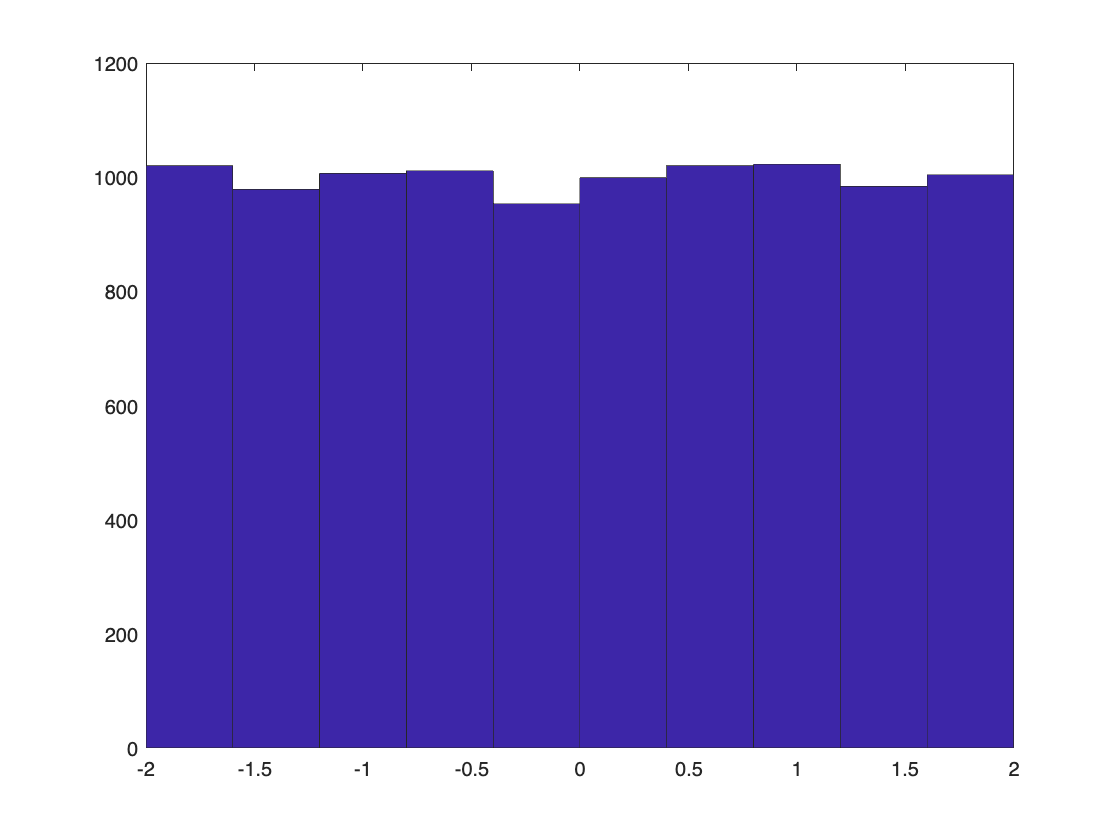

a = -2; b = 2;
U = a+(b-a)*rand(1,10000); hist(U)

- Amb nombres al·leatòris normals amb $\mu = 0$ i $\sigma = 1$

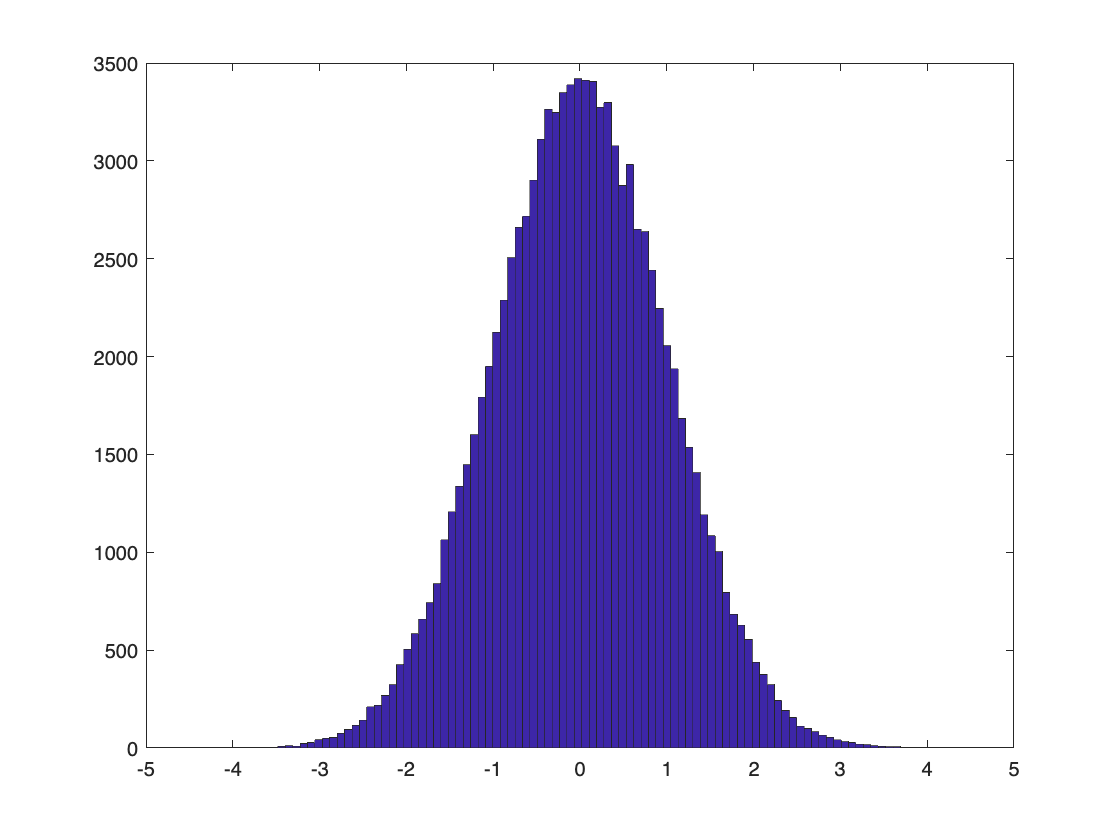

N=randn(1,100000); hist(N,100)

#### Exercici 5.  Sistemes triangulars superiors

Genereu un script en Matlab per trobar la solució d'un sistema lineal triangular superior pel mètode de substiució enrera. 

**JOC DE PROVES**

Resoleu els següents sistemes lineals:


$${\text a)}\ \left\{\begin{array}{rcr}
	3x-2y+z-t&=&8 \\ 4y-z+2t&=&-3\\ 2z+3t&=&11\\5t&=&15\end{array}\right.$$


U = [3 -2 1 -1; 0 4 -1 2; 0 0 2 3; 0 0 0 5], b = [8;-3;11;15]

U =      3    -2     1    -1
     0     4    -1     2
     0     0     2     3
     0     0     0     5


b =      8
    -3
    11
    15


x = backsubs(U,b)

x =      2
    -2
     1
     3


b)  Definiu la matriu  $U=\left(u_{ij}\right)_{15\times 15}$ i el vector  $b=(b_{i})_{15\times 1}$ com  $u_{ij}=\left\{\begin{array}{rr} \cos (ij) & i\leq j\,,\\ & \\ 0 & i>j\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=\tan (i)$

clearvars;
n = 15;
u = zeros(n);
for i = 1:n
    for j=i:n
        u(i,j) = cos(i*j);
    end
    b(i,1) = 1/(1+i^2);
end
TS = u(1:5,1:5), v=b(1:5,1)

TS =     0.5403   -0.4161   -0.9900   -0.6536    0.2837
         0   -0.6536    0.9602   -0.1455   -0.8391
         0         0   -0.9111    0.8439   -0.7597
         0         0         0   -0.9577    0.4081
         0         0         0         0    0.9912


v =     0.5000
    0.2000
    0.1000
    0.0588
    0.0385


#### Exercici 6.  Sistemes triangulars inferiors

Genereu un script en Matlab per trobar la solució d'un sistema lineal triangular inferior pel mètode de substiució endavant. 

**JOC DE PROVES**

Resoleu els següents sistemes lineals:


$${\text c)}\ \left\{\begin{array}{lcr}
	5x&=&-10 \\ x+3y&=&4\\ 3x+4y+2z&=&2\\-x+3y-6z-t&=&5\end{array}\right.$$


L = [5 0 0 0; 1 3 0 0; 3 4 2 0; -1 3 -6 -1]

L =      5     0     0     0
     1     3     0     0
     3     4     2     0
    -1     3    -6    -1


b = [-10;4; 2; 5]

b =    -10
     4
     2
     5


x = forward(L,b)

x =     -2
     2
     0
     3


d) Definiu la matriu  $l=\left(l_{ij}\right)_{20\times 20}$ i el vector  $b=(b_{i})_{20\times 1}$ com  $l_{ij}=\left\{\begin{array}{rr} i+j & i\geq j\,,\\ & \\ 0 & i<j\,, \end{array}\right.
\qquad\mbox{i}\qquad b_{i1}=i\,.$

clearvars;
n = 20;
u = zeros(n);
for i = 1:n
    for j=i:n
        u(i,j) = i+j;
    end
    b(i,1) = i;
end
TS = u(1:5,1:5), v=b(1:5,1)

TS =      2     3     4     5     6
     0     4     5     6     7
     0     0     6     7     8
     0     0     0     8     9
     0     0     0     0    10


v =      1
     2
     3
     4
     5


#### Exercici 7.  Eliminació gaussiana

Genereu un script de Matlab per trobar la solució d'un sistema lineal Ax=b pel mètodes d'eliminació gaussiana

** JOC DE PROVES**


$$e)\quad  A=\left (\begin{array}{rrrr}
		10 & -7 & 0 &  1\\
		-3 &  2 & 6 &  0\\
		5 & -1 & 5 &  0\\
		-1 &  0 & 2 & -1
		\end{array} \right)\quad\quad
	b=\left( \begin{array}{r} 7\\4\\6\\-3\end{array} \right).$$



$$f) \quad A=\left (\begin{array}{rrrr}
		 6 & -2  & 2 & 4\\
		12 & -4  & 2 & 2\\
		 3 & -13 & 9 & 3\\
		-6 &  4 & 1 & -18
	\end{array} \right)\quad\quad
	b=\left( \begin{array}{r} 12\\34\\27\\-38\end{array} \right).$$


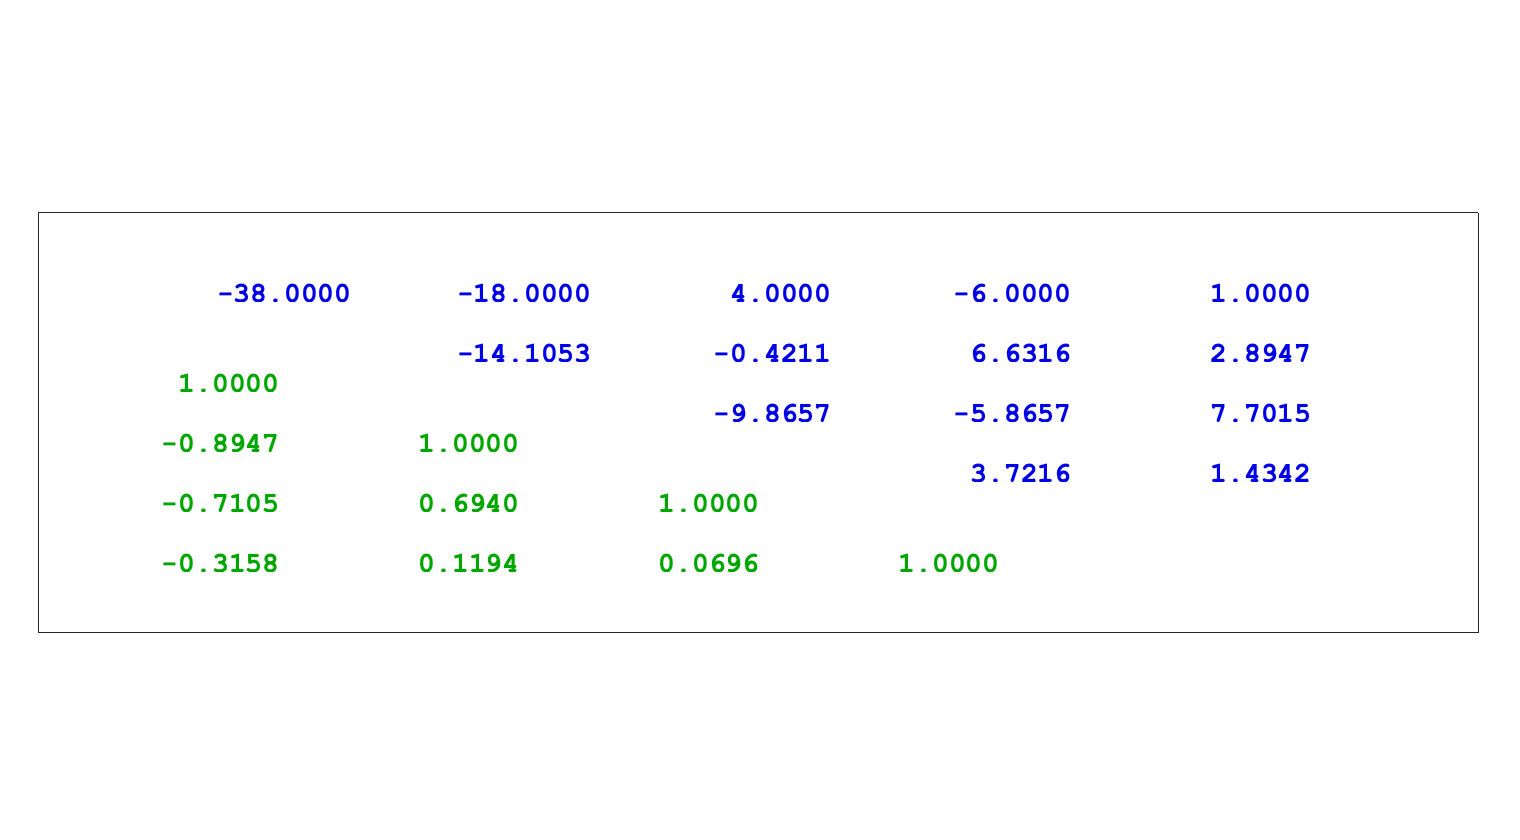

U =   -38.0000  -18.0000    4.0000   -6.0000    1.0000
         0  -14.1053   -0.4211    6.6316    2.8947
         0         0   -9.8657   -5.8657    7.7015
         0         0         0    3.7216    1.4342


AM=[6 -2 2 4 12; 12 -4 2 2 34; 3 -13 9 3 27; -6 4 1 -18 -38];
[~,U]=lugui(AM) 

x = backsubs(U(1:4,1:4),U(:,5))

x =    -0.1963
    0.0061
   -1.0098
    0.3854


AM(1:4,1:4)\AM(:,5)

ans =     1.9627
   -5.1429
   -5.0932
    0.0311


g) Definiu la matriu  $A=\left(a_{ij}\right)_{51\times 51}$ i el vector  $b=(b_{i})_{51\times 1}$ com  $a_{ij}=\left\{\begin{array}{rl} (-1)^{i} &\ i=j\,,\\ & \\ 2 &\ 1\le|i-j|\le 2\,, \end{array}\right.
	\qquad\mbox{i}\qquad b_{i}=i\,.$

clearvars;
n = 51; 
a = 2*ones(n);
for i=1:n
    a(i,i) = (-1)^i;
    b(i,1) = i;
end
a = a - triu(a,3);
a = a - tril(a,-3);
A = a(1:5,1:5), v = b(1:5,1)   

A =     -1     2     2     0     0
     2     1     2     2     0
     2     2    -1     2     2
     0     2     2     1     2
     0     0     2     2    -1


v =      1
     2
     3
     4
     5


### Mètodes compactes

#### Factoritzacions en Matlab®

Consulteu [LU, Txoleski i QR](https://es.mathworks.com/help/matlab/math/factorizations.html)

#### Exercici 8. Descomposició LU

Trobeu la descomposició LU de la matriu del sistema d'equacions lineals A i després resoleu el sistema d'equacions lineals Ax=b.


$$a) \qquad (A\,\vert\,b)=\left (
	\begin{array}{rrr|r}
		1 & 6 & 0\  & \ 3\\
		2 & 1 & 0\  & \ 1\\
		0 & 2 & 1\  & \ 1
	\end{array}\right )$$



$$b)\quad	(A\,\vert\,b)=\left ( \begin{array}{rrrr|r}
		6 & -2 & 2 & 4\ &\  0\\
		12& -8 & 4 & 10\  &\  -10\\
		3 & -13 & 3 & 3\  &\  -39\\
		-6 & 4 & 2 & -18\  &\  -16
	\end{array}\right ),$$


A=[6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18]

A =      6    -2     2     4
    12    -8     4    10
     3   -13     3     3
    -6     4     2   -18


[L, U, P] = lu(A)

L =     1.0000         0         0         0
    0.2500    1.0000         0         0
   -0.5000         0    1.0000         0
    0.5000   -0.1818    0.0909    1.0000


U =    12.0000   -8.0000    4.0000   10.0000
         0  -11.0000    2.0000    0.5000
         0         0    4.0000  -13.0000
         0         0         0    0.2727


P =      0     1     0     0
     0     0     1     0
     0     0     0     1
     1     0     0     0


b = [0 -10 -39 -16]'

b =      0
   -10
   -39
   -16


% primer pas
y = forward(L,P*b)

y =   -10.0000
  -36.5000
  -21.0000
    0.2727


% segon pas
x = backsubs(U,y)

x =     1.0000
    3.0000
   -2.0000
    1.0000


U\(L\P*b)

ans =     1.0000
    3.0000
   -2.0000
    1.0000


% control:: vector residu
r = b-A*x

r = 1.0e-14 *

   -0.0444
   -0.1776
         0
         0


    
$$c)\quad \left\{ \begin{array}{rcrcrcrcr}
	6x_1 &+& 2x_2 &-& x_3&-& x_4&=&0\\
	2x_1 &+& 4x_2 &+& x_3& & &=&7\\
	-x_1 &+& x_2 &+& 4x_3 &-& x_4 &=&-1\\
	-x_1 & & &-& x_3&+&3x_4&=&-2
	\end{array}\right.$$


#### Exercici 9. Inversa d'una matriu a partir de la descomposició LU


$$	a)\quad  A=\left ( \begin{array}{rrrr}
	6 & 2 & 1 & -1 \\
	2 & 4 & 1 & 0 \\
	1 & 1 & 4 & -1 \\
	-1 & 0 & -1 & 3
	\end{array}\right )$$$$


A = [6 2 1 -1; 2 4 1 0; 1 1 4 -1; -1 0 -1 3]

A =      6     2     1    -1
     2     4     1     0
     1     1     4    -1
    -1     0    -1     3


[L,U,P]=lu(A)

L =     1.0000         0         0         0
    0.3333    1.0000         0         0
    0.1667    0.2000    1.0000         0
   -0.1667    0.1000   -0.2432    1.0000


U =     6.0000    2.0000    1.0000   -1.0000
         0    3.3333    0.6667    0.3333
         0         0    3.7000   -0.9000
         0         0         0    2.5811


P =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Primera columna 

B = eye(size(A))

B =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


b = B(:,1)

b =      1
     0
     0
     0


x1 = U\(L\P*b)

x1 =     0.2147
   -0.1047
   -0.0105
    0.0681


Segona columna

b = B(:,2)

b =      0
     1
     0
     0


x2 = U\(L\P*b)

x2 =    -0.1047
    0.3194
   -0.0681
   -0.0576


Tercera columna

b = B(:,3)

b =      0
     0
     1
     0


x3 = U\(L\P*b)

x3 =    -0.0105
   -0.0681
    0.2932
    0.0942


Quarta columna

b = B(:,4)

b =      0
     0
     0
     1


x4 = U\(L\P*b)

x4 =     0.0681
   -0.0576
    0.0942
    0.3874


Control/verificació

iA = [x1,x2,x3,x4]

iA =     0.2147   -0.1047   -0.0105    0.0681
   -0.1047    0.3194   -0.0681   -0.0576
   -0.0105   -0.0681    0.2932    0.0942
    0.0681   -0.0576    0.0942    0.3874


format default
A*iA, iA*A

ans =     1.0000    0.0000    0.0000         0
   -0.0000    1.0000         0    0.0000
   -0.0000    0.0000    1.0000         0
   -0.0000    0.0000   -0.0000    1.0000


ans =     1.0000   -0.0000    0.0000   -0.0000
   -0.0000    1.0000   -0.0000    0.0000
    0.0000         0    1.0000   -0.0000
         0   -0.0000         0    1.0000


U\(L\P*B)

ans =     0.2147   -0.1047   -0.0105    0.0681
   -0.1047    0.3194   -0.0681   -0.0576
   -0.0105   -0.0681    0.2932    0.0942
    0.0681   -0.0576    0.0942    0.3874



$$b)\quad A=\left(\begin{array}{cccc}
		1&2&3&4\\1&4&9&16\\1&8&27&64\\1&16&81&216\end{array}\right)$$


#### Exercici 10. Mètode QR

Trobeu la descomposició QR de la matriu del sistema d'equacions lineals A i després resoleu el sistema d'equacions lineals AX=b següents


$$a)\ \left\{ \begin{array}{rcr}
			6x_1 + 2x_2 - x_3 - x_4&=&0\\
			2x_1 + 4x_2 + x_3 &=&7\\
			-x_1 + x_2 + 4x_3 - x_4 &=&-1\\
			-x_1 - x_3+3x_4&=&-2
		\end{array}\right.$$


A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3];
b = [0; 7; -1; -2];
[qq,rr] = qr(A);
x = rr\qq.'*b

x =    -1.6291
    3.0331
   -1.8742
   -1.8344



$$b)\ \left\{ \begin{array}{rcr}
			0.05x_1+0.07x_2+0.06x_3+0.05x_4&=&0.23\\
			0.07x_1+0.10x_2+0.08x_3+0.07x_4&=&0.32\\
			0.06x_1+0.08x_2+0.10x_3+0.09x_4&=&0.33\\
			0.05x_1+0.07x_2+0.09x_3+0.10x_4&=&0.31
			\end{array}\right.$$


function x = forward(L,x)
% FORWARD. Forward elimination.
% For lower triangular L, x = forward(L,b) solves L*x = b.
[n,n] = size(L);
    for k = 1:n
        j = 1:k-1;
        x(k) = (x(k) - L(k,j)*x(j))/L(k,k);
        end
end
function x = backsubs(U,x)
% BACKSUBS. Back substitution.
% For upper triangular U, x = backsubs(U,b) solves U*x = b.
[n,n] = size(U);
    for k = n:-1:1
        j = k+1:n;
        x(k) = (x(k) - U(k,j)*x(j))/U(k,k);
    end
end

`Document preparat per M. Àngela Grau Gotés 1 de març de 2023`